normal

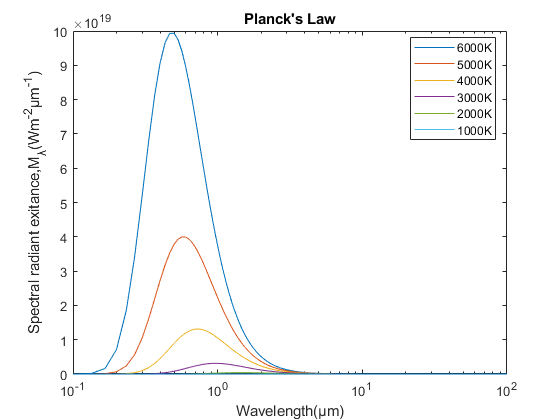

clear;clc;clf
h = 6.626*(10^-34);  % 普朗克常數  千克/米2/秒-1
k = 1.38*(10^-23);   % 波茲曼常數
c = 3*(10^8);        % 光速
len = linspace(0.1,100,3000)*(10^-6); % 波長
t = [6000 5000 4000 3000 2000 1000 500 300];
lenmu = len*10^6;
for i = 1:length(t)
    Mlen{i} = (2*pi*h*(c^2))./((exp(h*c./(k.*t(i).*len)))-1)./(len.^5);
%     Mlen{i} = (2*pi*h*(3.74177153*(10^-16)^2))./((exp(h*1.438777*(10^-2)./(k.*t(i).*len)))-1)./(len.^5);
    Mlen{i} = Mlen{i}.*(10^6);
    semilogx(lenmu,Mlen{i})
%     loglog(lenmu,Mlen{i})
%     plot(lenmu,Mlen{i})
    hold on
end
hold off

title('Planck''s Law')
ylabel(['Spectral radiant exitance,M_λ' '(Wm^-^2' 'μm^-^1)'])
xlabel('Wavelength(μm)')
% axis([0.1 3.5 0 10^14])
%3.74177153*10^-16     1.438777*10^-2
legend('6000K','5000K','4000K','3000K','2000K','1000K','Location','best')

log-log

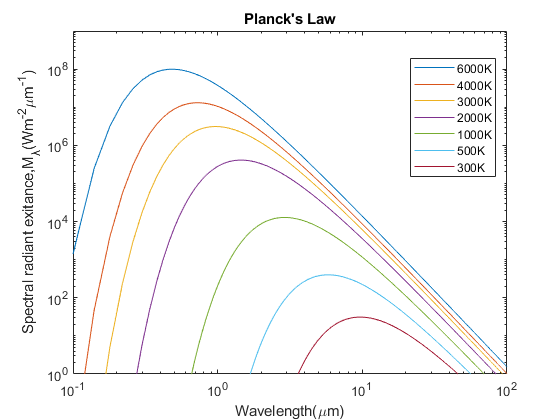

clc;clear;clf
h = 6.626*(10^-34);  % 普朗克常數  千克/米2/秒-1
k = 1.38*(10^-23);   % 波茲曼常數
c = 3*(10^8);        % 光速
c1 = 2*pi*h*(c^2)*10^16;
c2 = 10^6*h*c./k;
% simple model of the black body using MATLAB/Octave/Freemat
len = linspace(0.1,100,2500);     % microns sweep over a range of wavelengths
% wavelength = 0.1:0.01:100;     % microns sweep over a range of wavelengths
T = [6000 4000 3000 2000 1000 500 300];             % temperature in kelvin
for i=1:length(T)
% Wlen = (2*pi*h*(c^2))./((wavelength.^5).*((exp(h*c./(k*T1.*wavelength)))-1))*10^8; % gives the result in W/m2/um x 1e8
    Wlen = c1./((len.^5).*(exp(c2./(T(i).*len))-1)); % gives the result in W/m2/um x 1e8
% plot(wavelength,F);
    loglog(len,Wlen*10^8);
    hold on
end

axis([0.1 100 1 10^9])
title('Planck''s Law')
ylabel(['Spectral radiant exitance,M_λ' '(Wm^-^2' '\mum^-^1)'])
xlabel('Wavelength(\mum)')
%3.74177153*10^-16     1.438777*10^-2
legend('6000K','4000K','3000K','2000K','1000K','500K','300K','Location','best')